# SVIR Infectious Disease Model with 1 intervention

clear all
close all

% this is a simple SIR model with 4 main categories: S = susceptible, V =
% vaccinated, I = infected (infectious), R = recovered (removed)

% the differential equations we need to solve are below. 



$$\frac{\partial S}{\partial t}=-\beta SI-\nu S+\omega V+\mu R\textrm{
}$$

$$,$$



$$\frac{\partial V}{\partial t}=+\nu S-\omega V$$



$$\frac{\partial I}{\partial t}=+\beta SI-\gamma I$$



$$\frac{\partial R}{\partial t}=+\gamma I-\mu R$$


where $\beta$ is the rate of S to I, $\nu$ is the rate from S to V, $\omega$ is the rate of vaccinated (V) going back to susceptible (S), $\mu$ is the rate of recovered becoming susceptible again, and $\gamma$ is the rate of going from I to R. 

In general, any of the rate constants can depend on time, but we will only allow 1 of them to change with time in this code. Namely, the rate of susceptible people getting vaccinated is directly proportional to the number of people currently infected ... 

We first initialize each of the 4 "states" from 1 to 0. Then, using a forward euler explicit method to solve this, ...

tt = 1; % time stepping variable initial value (start at time 1)
t_max = 365*24; % total number of time steps (set up hourly)
dt = 1; % size of time step (currently 1 hour)

% "states"
S(tt,1) = 0.999;
V(tt,1) = 0;
I(tt,1) = 0.001; % if starting off with no infected, there will never be any change to the equations of state
R(tt,1) = 0;


% first initializing the rates, we will state that beta, omega, and gamma don't depend on time, but nu will.
% nu is the rate of susceptible getting vaccinated, which we will scale
% based on the number of currently infected. So, 



$$\nu =\alpha \;I\;$$


## Initializing variables

beta = 0.006; % rate of S to I
alpha = 0.0022; % contributes to rate of S to V
nu(tt) = alpha.*I(tt); % rate of S to V
omega = 0.00041; % rate of V to S
gamma = 0.00053; % rate of I to R
mu = 0.0003; % rate from R to S

## Time stepping loop

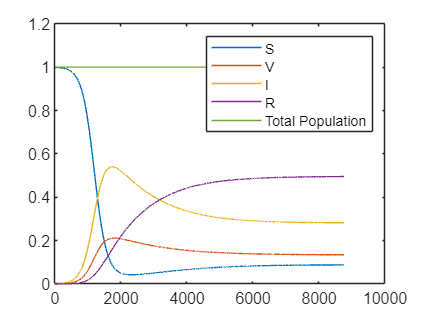

%  Forward euler method
for tt = 2:t_max
    nu(tt,1) = alpha.*I(tt-1,1); % rate of S to V
    S(tt,1) = dt.*(-beta*S(tt-1,1).*I(tt-1,1) - nu(tt).*S(tt-1) + omega.*V(tt-1,1) + mu.*R(tt-1,1)) + S(tt-1,1);
    V(tt,1) = dt.*(+nu(tt).*S(tt-1,1) - omega.*V(tt-1,1)) + V(tt-1,1);
    I(tt,1) = dt.*(beta.*S(tt-1,1).*I(tt-1,1) - gamma.*I(tt-1,1)) + I(tt-1,1);
    R(tt,1) = dt.*(gamma.*I(tt-1,1)- mu.*R(tt-1,1)) + R(tt-1,1);

end
figure(1)
plot(1:t_max, S(:,1)); 
hold on
plot(1:t_max, V(:,1)); 
plot(1:t_max, I(:,1)); 
plot(1:t_max, R(:,1)); 
plot(1:t_max,S+V+I+R);
legend('S','V','I','R','Total Population')
hold off